## Connect to the hardware

Once you've set up the Arduino, you can connect to it from MATLAB. You can also connect to the motor carrier, which will be used to communicate with the other peripherals on the robot.

clear
a = arduino;
carrier = motorCarrier(a);

## Control the servo

The servo motor is used to raise and lower the whiteboard markers. It should be connected to the SERVO3 port on the carrier. Create a variable in MATLAB to control it.

s = servo(carrier,3);

Keep calling writePosition, changing the value by a small amount each time. Explore different values until you figure out which values to use for lowering the left marker, lowering the right marker, and raising both markers.

pos = 0.44; %Change this value and continue running this section
writePosition(s,pos)

Once you've identified the servo values for lowering the left and right markers, store them in variables, and save them to a MAT-file. You'll load these values in future exercises that require raising and lowering the markers.

LeftMarker = 0.4;  %Change this to the LeftMarker value on your robot
RightMarker = 0.65; %Change this to the RightMarker value on your robot
NoMarker = mean([LeftMarker RightMarker]);

save ServoPositions.mat LeftMarker RightMarker NoMarker

Base = 0.795; %Change this to the Base distance for your robot (meters)
save RobotGeometry.mat Base


## **Define motor specifications**

V_rated = 12; %Volts
w_free = 300;            %rev/min
TauStall = 2.220; %kg-cm
V_battery = 3.7; %Volts

## **Define whiteboard dimensions**

H_board = 0.6; %Change this to the height value for your whiteboard (meters)


## **Define robot constants**

r_spool = 0.0045;   %m
Mass = 0.25;       %kg (You can modify this based on the actual weight of your robot.)
Weight = Mass*9.81; %N

pulleyBuffer = 0.05; %Minimum distance to pulley (meters)
L_arm = 0.075;       %meters
H_robot = 0.19;      %meters
r_pulley = 0.0075;   %meters

## **Choose drawable region limits and visualize**

pickedX = 0.06; %Change this to your chosen minimum x-value (meters)
pickedY = 0.13; %Change this to your chosen minimum y-value (meters)


## Choose drawable region limits and visualize

After choosing a point as the minimum *xy*-coordinate, enter it in the following section of code. Execute this section to visualize the drawable area.

TauMax = 0.0201

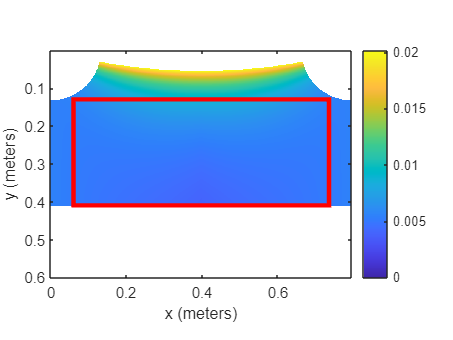

run WhiteboardLimits.mlx